# `Project = B-spline Trajectory Optimization` 

% Author  : Brijeshkumar Vijaykumar Panchal
% E-Mail-Adresse: bpanchal@stud.hs-heilbronn.de
% Matriculation Number : 221607
% Supervisor : Prof. Dr.-Ing. Peter Ott 
% E-Mail-Adresse: peter.ott@hs-heilbronn.de
% Date : 28.06.2024

## `Introduction` :-

- This project aims to generate a trajectory using B-splines and optimize it to minimize the time taken for traversal.

- B-splines offer flexibility and precision in modeling curves, making them suitable for trajectory optimization.

- The optimization process adjusts intermediate control points to minimize travel time while considering dynamic constraints and obstacle avoidance.

###         **B-splines and NURBS**** :-**

- B-splines (Basis Splines) and NURBS (Non-Uniform Rational B-Splines) are fundamental tools in computer graphics, CAD, and many other fields due  to their flexibility and precision in modeling curves and surfaces.

###         **Important Properties of B-splines**** :-**

- **Locality:** Coefficients only change behavior in a local neighborhood, allowing for local control over the shape of the spline.

- **Derivatives:** The derivatives of B-splines are again B-splines of lower order, simplifying the computation of slopes and curvatures.

- **Convex Hull Property:** The spline piece is contained within the convex hull of a subset of the control points, providing geometric intuition and control.

- **Affine Transformation:** An affine transformation of the coordinates (such as rotation or scaling) can be performed by applying the transformation to the control points of the B-spline.

- **Discontinuities:** Discontinuities of B-spline or its derivatives can be generated by multiple interior knots, allowing for flexible modeling of piecewise smooth shapes.

- **Knot Vector:** For fitting a B-spline to data, a knot vector must be provided. The optimal knot vector is not automatically determined and needs to be specified. For a given knot vector, there is a unique least-square solution of the coefficients of the B-spline under certain conditions.

- **NURBS:** NURBS are part of the IGES and STEP standards for CAD data exchange, making them crucial for interoperability in engineering applications.

#### (1) Initial **Generate B-spline Trajectory** :-

- B-splines are a type of piecewise-defined polynomial function used for smooth curve fitting and interpolation. They are widely used in computer graphics, computer-aided design (CAD), and numerical analysis due to their flexibility and ability to approximate complex curves.

- B-splines are used to create smooth and flexible curves that pass near the given control points. The `spline` function in MATLAB generates a B-spline curve based on the parametric values and the control points.

- Plotting the original trajectory helps visualize the initial path  defined by the B-spline before any optimization. This visualization is  crucial for understanding how the initial control points influence the shape of the trajectory.

- **Parametric Values (**`u_S`**) : **The parametric values represent the "time" parameter along the trajectory. These values are typically normalized to the range [0, 1], where 0 corresponds to the start of the trajectory and 1 corresponds to the end.

- **Control Points (**`xs`** and **`ys`**) : **Control points are the key elements that define the shape of the B-spline curve. They are specified in pairs of x and y coordinates 

- **Degree of the B-spline (**`g`**) : **The degree '`g'` determines the polynomial degree of each segment of the B-spline curve. Higher degrees allow more flexibility but can lead to oscillations if not properly controlled.

- **B-spline Interpolation (**`spapi`** function) : **MATLAB provides the `spapi` function to create a B-spline interpolation (`spi`). This function constructs a B-spline curve that passes through the specified control points (`xs`, `ys`) based on the given parametric values and degree (`g`).

- **Knot Vector : **The knot vector defines the sequence of parameter values where each segment of the B-spline curve is defined. It plays a crucial role in determining the continuity and smoothness of the curve.

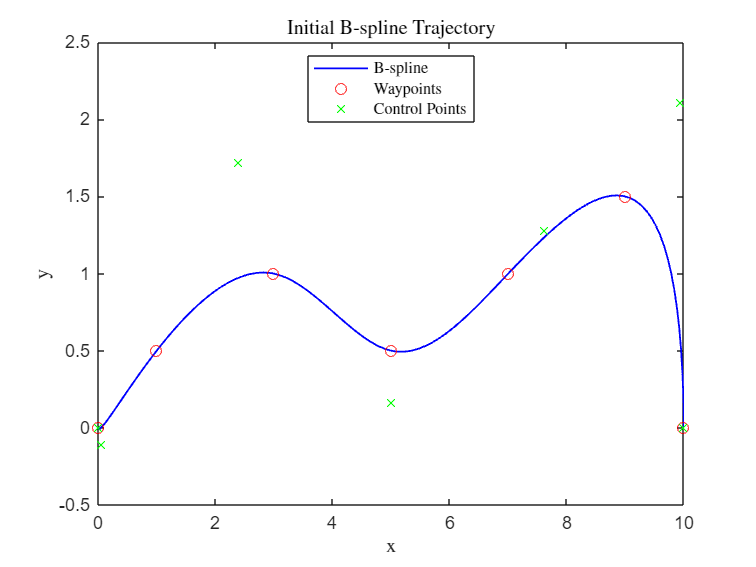

% Define control points

xs = [0, 1, 3, 5, 7, 9, 10]; % x coordinates of waypoints
ys = [0, 0.5, 1, 0.5, 1, 1.5, 0]; % y coordinates of waypoints

g = 3; % Degree of the B-spline
u_S = linspace(0, 1, numel(xs)); % Parametric values for waypoints

spi = spapi(g + 1, u_S, [xs; ys]); % Create B-spline interpolation
p = spi.coefs; % Extract coefficients of the B-spline

% Plot initial B-spline trajectory
figure;
fnplt(spi, 1, 'b');
hold on;
plot(xs, ys, 'or'); % Plot waypoints
plot(p(1,:), p(2,:), 'xg'); % Plot control points
xlabel('x', 'Interpreter', 'latex');
ylabel('y', 'Interpreter', 'latex');
title('Initial B-spline Trajectory', 'Interpreter', 'latex');
legend({'B-spline', 'Waypoints', 'Control Points'}, 'Location', 'best', 'Interpreter', 'latex');
hold off;

**Explanation:**

- **Waypoints (**`xs`**, **`ys`**)**: These are the given points through which you want the spline to pass.

- **Control Points (**`p`**)**: These are the points used internally by the B-spline to determine its shape. They are derived from the waypoints and are not necessarily the same as the waypoints.

- **Spline Plot (**`fnplt(spi, 1, 'b')`**)**: This plots the B-spline based on the control points.

- **Waypoints Plot (**`plot(xs, ys, 'or')`**)**: This plots the original waypoints in red circles.

- **Control Points Plot (**`plot(p(1,:), p(2,:), 'xg')`**)**: This plots the control points in green crosses.

#### (2) B-Spline OPtimization - **Minimize Time :-**

- In this section, we aim to optimize the trajectory to minimize the time  taken to traverse it. This is achieved by adjusting the intermediate  control points through an optimization process. The objective function for  the optimization is to minimize the norm of the differences in the  trajectory, which indirectly minimizes the time. We will also consider innovative features such as obstacle avoidance and dynamic constraints.

- The objective function `traversal_time` computes the traversal time based on the B-spline coefficients.

- The optimization is performed using MATLAB's `fmincon` function, which minimizes the `traversal_time` objective function subject to constraints.

- Initial coefficients (`coefs0`) are optimized to minimize the traversal time, adjusting the trajectory to potentially reduce path length or maximize efficiency.

- Constraints such as fixed control points (`fixed_points`) are enforced to maintain desired trajectory characteristics.

% Define knot vector
num_control_points = length(xs);
knot_vector = augknt([zeros(1, g) linspace(0, 1, num_control_points - g + 1) ones(1, g)], g + 1);

spi = spapi(knot_vector, linspace(0, 1, num_control_points), [xs; ys]);

function cost = traversal_time(coefs, degree, knots, fixed_points)
    % Reshape coefficients to matrix form
    coefs = reshape(coefs, 2, []);
    % Reinstate fixed points
    coefs(:, 1) = fixed_points(:, 1);
    coefs(:, end) = fixed_points(:, 2);
    % Create B-spline with current coefficients
    sp = spmak(knots, coefs);

    % Evaluate the B-spline at a fine grid of parameter values
    u_fine = linspace(0, 1, 100); 
    spline_vals = fnval(sp, u_fine);

    % Calculate distances between consecutive points on the spline
    distances = sqrt(sum(diff(spline_vals, 1, 2).^2, 1));

    % Assume a constant speed for simplicity (adjust as needed)
    speed = 1; % Constant speed (can be adjusted based on application)
    
    % Estimate traversal time
    time_intervals = distances / speed;

    % Total traversal time is the sum of time intervals
    cost = sum(time_intervals);
end

% Define optimization variables
initial_coefs = spi.coefs;
num_coefs = numel(initial_coefs);

coefs0 = initial_coefs(:); % Initial coefficients as vector

% Define fixed points (first and last control points)
fixed_points = [xs(1), xs(end); ys(1), ys(end)];

% Define optimization options
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'interior-point', 'MaxIterations', 1000);

% Define constraints for other control points
Aeq = [];
beq = [];

% Define lower and upper bounds for optimization
lb = coefs0 - 1; % Lower bound
ub = coefs0 + 1; % Upper bound

% Run optimization
[optimized_coefs, fval, exitflag] = fmincon(@(coefs) traversal_time(coefs, g, knot_vector, fixed_points), coefs0, [], [], Aeq, beq, lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      15    1.170567e+01    0.000e+00    4.484e-01
    1      30    1.099948e+01    0.000e+00    3.536e-01    7.664e-01
    2      46    1.069228e+01    0.000e+00    1.697e-01    4.150e-01
    3      61    1.049021e+01    0.000e+00    1.003e-01    3.632e-01
    4      76    1.034579e+01    0.000e+00    4.378e-02    3.533e-01
    5      91    1.031177e+01    0.000e+00    2.474e-02    1.166e-01
    6     106    1.030591e+01    0.000e+00    2.000e-02    6.032e-02
    7     121    1.025851e+01    0.000e+00    2.925e-02    2.444e-01
    8     136    1.024468e+01    0.000e+00    1.670e-02    9.841e-02
    9     151    1.024112e+01    0.000e+00    1.581e-02    1.289e-01
   10     166    1.023333e+01    0.000e+00    2.026e-02    3.649e-01
   11     181    1.023386e+01    0.000e+00    1.410e-02    2.366e-02
   12     196    1.023374e+01    0.000e+00    4

% Display optimized coefficients
disp('Optimized coefficients:');

Optimized coefficients:


disp(optimized_coefs');

    0.0000    0.0000    0.2562   -0.0360    3.0108    0.9884    5.9999    0.4111    6.9892    0.6949    9.0797    0.6178   10.0000    0.0000



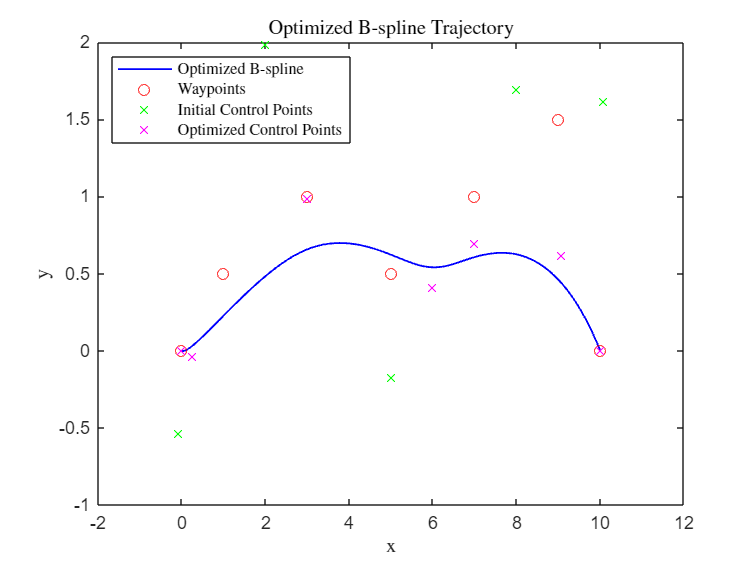


% Reshape optimized coefficients
optimized_coefs = reshape(optimized_coefs, size(initial_coefs));
optimized_coefs(:, 1) = fixed_points(:, 1); % Reinstate fixed points
optimized_coefs(:, end) = fixed_points(:, 2);

% Create optimized B-spline with optimized coefficients
optimized_sp = spmak(knot_vector, optimized_coefs);

% Plot optimized B-spline trajectory
figure;
fnplt(optimized_sp, 1, 'b');
hold on;
plot(xs, ys, 'or'); % Plot waypoints
plot(initial_coefs(1,:), initial_coefs(2,:), 'xg'); % Plot initial control points
plot(optimized_coefs(1,:), optimized_coefs(2,:), 'xm'); % Plot optimized control points
xlabel('x', 'Interpreter', 'latex');
ylabel('y', 'Interpreter', 'latex');
title('Optimized B-spline Trajectory', 'Interpreter', 'latex');
legend({'Optimized B-spline', 'Waypoints', 'Initial Control Points', 'Optimized Control Points'}, 'Location', 'northwest', 'Interpreter', 'latex');
hold off;

- After optimization, the script plots the optimized B-spline trajectory alongside the original control points (`xs`, `ys`).

- Visualization helps in assessing how the optimized trajectory deviates from the original, highlighting improvements in terms of time minimization and path smoothness.

- The number and positioning of control points (`xs`, `ys`) and knots (`knot_vector`) significantly influence the spline's flexibility and accuracy in approximating the desired path.

% display initial traversal time
initial_time = traversal_time(initial_coefs(:), g, knot_vector, [xs(1), xs(end); ys(1), ys(end)]);
disp(['Initial total traversal time: ', num2str(initial_time)]);

Initial total traversal time: 11.7057


% Display optimized total traversal time
disp(['Optimized total traversal time: ', num2str(fval)]);

Optimized total traversal time: 10.2087


- **Conclusion :** Understanding the theoretical underpinnings of optimizing B-spline trajectories to minimize traversal time provides valuable insights into trajectory planning and optimization tasks. This approach not only enhances control and precision in trajectory design but also supports real-world applications requiring efficient path planning, such as autonomous vehicles, robotics, and aerial drone navigation. 

- **Note:** It's important to note that in trajectory optimization, the concept of minimizing traversal time using B-spline trajectories doesn't inherently consider straight lines, which represent the shortest route between two points. Instead, the optimization focuses on adjusting the B-spline's control points to potentially reduce path length or maximize efficiency while adhering to specified constraints and objectives. This approach allows for precise trajectory planning that takes into account real-world factors like obstacles, vehicle dynamics, and operational requirements.

### `(3) `Exploring Interpolation Techniques and B-spline Modeling

**Interpolation :-**

- Interpolation is the process of estimating unknown values that fall between known values. In MATLAB, the `interp1` function is used for 1D interpolation and `griddata` for 2D interpolation.

**Interpolation in 1D :-**

- The `interp1` function in MATLAB performs 1D interpolation.  It estimates the value of a function for intermediate points between the given data points.

**Example **:

% y_ip = interp1(xs, ys, x_ip, method);

**Where **`method`** can be :**

- **'linear' (default):** Linear interpolation.

- **'pchip':** Shape-preserving piecewise cubic interpolation.

- **'cubic':** Cubic convolution.

- **'makima':** Modified Akima cubic Hermite interpolation.

- **'spline':** Spline interpolation using not-a-knot end conditions.

**Interpolation in 2D :**

- The `griddata` function is used for 2D interpolation based on Delaunay triangulation. It interpolates the surface at specified points.

**Example :**

% z_ip = griddata(xs, ys, zs, x_ip, y_ip, method);

**Where **`method`** can be :**

- **'linear' : **Linear interpolation 

- **'nearest' : **Nearest neighbor interpolation 

- **'natural' : **Natural spline interpolation

- **'cubic' : **Cubic convolution interpolation

- **'v4' : ** 'v4' interpolation 

`B-spline Modeling:`

- `B-splines are widely used for modeling smooth curves and surfaces. They offer local control, flexibility, and desirable mathematical properties. Applications of B-splines include computer graphics, CAD, animation, and more. In this project, B-splines are utilized to generate and optimize trajectories.The combination of B-splines with optimization techniques allows for efficient trajectory planning with consideration of dynamic constraints, obstacle avoidance, and uncertainty modeling.In this project, waypoints are predefined points that represent specific locations through which the trajectory must pass. These waypoints define the initial path for the B-spline curve, and the optimization process adjusts them to minimize the travel time along the trajectory.`

`In Engineering, B-splines find applications in:`

- `Design and modeling of mechanical components with complex shapes.`

- `Finite Element Analysis (FEA) for stress analysis and structural optimization.`

- `Motion planning and path generation for robotic systems, including manipulators and autonomous vehicles.`

- `Control systems design, where smooth trajectories are required for precise motion control.`

- `Trajectory planning of robotic arms in manufacturing processes.`

- `Autonomous navigation of mobile robots in warehouses and outdoor environments.`

- `Designing smooth and natural motion profiles for robotic prosthetics and exoskeletons.`

- `Simulation and control of unmanned aerial vehicles (UAVs) for surveillance and reconnaissance missions.`

**MATLAB Code for B-spline Reproduction of Grid Data**

- This section demonstrates how to reproduce grid data using a B-spline.  The order of the spline and the sites (not knots) must be specified.

% g = 3; % order (cubic spline)
% u_x = linspace(0, 1, Nx_S); 
% v_y = linspace(0, 1, Ny_S); % sites of S (not knots!)
% spi = spapi({g+1, g+1}, {u_x, v_y}, S); % make spline (data is exactly reproduced)

**MATLAB Code for Fitting a B-spline**

- This section demonstrates fitting a B-spline to grid data in a  least-square sense. Clamped uniform knots with specified multiplicity  are used.

% m_u = Nx_c + g + 1; 
% m_v = Ny_c + g + 1;
% u_x = linspace(0, 1, Nx_S); 
% v_y = linspace(0, 1, Ny_S); % sites of S (may also be chosen non-uniformly)
% knots = {augknt(linspace(u_x(1), u_x(end), m_u-2*g), g+1), augknt(linspace(v_y(1), v_y(end), m_v-2*g), g+1)};
% sp2 = spap2(knots, [g+1 g+1], {u_x, v_y}, S); % fit spline

### **Conclusion ****:**

- This project successfully demonstrates the generation of a B-spline  trajectory and its optimization to minimize the time taken for  traversal. The theory and mathematical background of B-splines,  interpolation methods, and the MATLAB code for B-spline fitting provide a comprehensive understanding of the concepts used in this project.